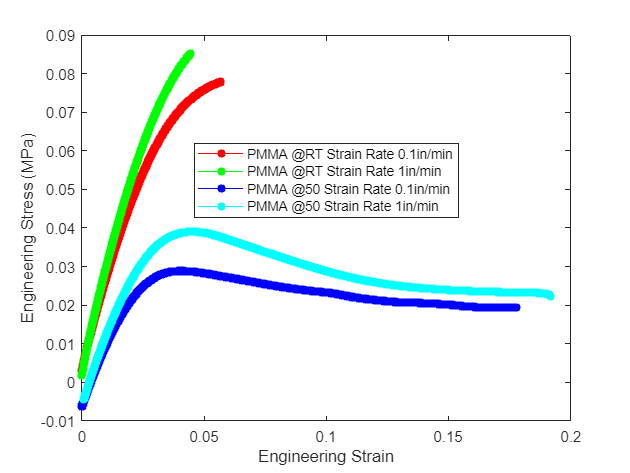

% Vinay's PMMA Plotting Code:

% Open .csv file and retrieve data
PMMA = '/Users/vinay/Downloads/PMMA_S6_1 (2).csv';
PMMA_data = readtable(PMMA,'HeaderLines',13);

% Define material properties
PMMA_rt1_width = 13.21;
PMMA_rt1_thickness = 3.07;
PMMA_rt1_length = 89.18;

PMMA_rt2_width = 13.16;
PMMA_rt2_thickness = 3.2;
PMMA_rt2_length = 92.38;

PMMA_501_width = 12.57;
PMMA_501_thickness = 3.25;
PMMA_501_length = 90.65;

PMMA_502_width = 13.03;
PMMA_502_thickness = 3.2;
PMMA_502_length = 91.26;

% Extract data from tables, be careful here to use correct indices
% Likely have to scan through csv file to obtain correct indices    
PMMA_rt1_time = PMMA_data{1:5995, 2};
PMMA_rt1_displacement = PMMA_data{1:5995, 3};
PMMA_rt1_force = PMMA_data{1:5995, 4};

PMMA_rt2_time = PMMA_data{6004:6493, 2};
PMMA_rt2_displacement = PMMA_data{6004:6493, 3};
PMMA_rt2_force = PMMA_data{6004:6493, 4};

PMMA_501_time = PMMA_data{6501:25572, 2};
PMMA_501_displacement = PMMA_data{6501:25572, 3};
PMMA_501_force = PMMA_data{6501:25572, 4};

PMMA_502_time = PMMA_data{25574:27632, 2};
PMMA_502_displacement = PMMA_data{25574:27632, 3};
PMMA_502_force = PMMA_data{25574:27632, 4};

% Calculate engineering stress and strain values for each material,
% tabularize because it's easy to troubleshoot by displaying the tables
PMMA_rt1_egrstress = PMMA_rt1_force ./ (PMMA_rt1_width * PMMA_rt1_thickness);
PMMA_rt1_egrstrain = PMMA_rt1_displacement ./ PMMA_rt1_length;
PMMA_rt1_table = table(PMMA_rt1_time,PMMA_rt1_egrstrain,PMMA_rt1_egrstress);

PMMA_rt2_egrstress = PMMA_rt2_force ./ (PMMA_rt2_width * PMMA_rt2_thickness);
PMMA_rt2_egrstrain = PMMA_rt2_displacement ./ PMMA_rt2_length;
PMMA_rt2_table = table(PMMA_rt2_time,PMMA_rt2_egrstrain,PMMA_rt2_egrstress);

PMMA_501_egrstress = PMMA_501_force ./ (PMMA_501_width * PMMA_501_thickness);
PMMA_501_egrstrain = PMMA_501_displacement ./ PMMA_501_length;
PMMA_501_table = table(PMMA_501_time,PMMA_501_egrstrain,PMMA_501_egrstress);

PMMA_502_egrstress = PMMA_502_force ./ (PMMA_502_width * PMMA_502_thickness);
PMMA_502_egrstrain = PMMA_502_displacement ./ PMMA_502_length;
PMMA_502_table = table(PMMA_502_time,PMMA_502_egrstrain,PMMA_502_egrstress);

% Plot the data for each material, plot of points with line connecting them
plot(PMMA_rt1_egrstrain, PMMA_rt1_egrstress, 'r-o', 'MarkerFaceColor', 'red','MarkerSize', 5);
hold on
plot(PMMA_rt2_egrstrain, PMMA_rt2_egrstress, 'g-o', 'MarkerFaceColor', 'green','MarkerSize', 5);
plot(PMMA_501_egrstrain, PMMA_501_egrstress, 'b-o', 'MarkerFaceColor', 'blue','MarkerSize', 5);
plot(PMMA_502_egrstrain, PMMA_502_egrstress, 'c-o', 'MarkerFaceColor', 'cyan','MarkerSize', 5);

xlabel('Engineering Strain');
ylabel('Engineering Stress (MPa)');
legend('PMMA @RT Strain Rate 0.1in/min','PMMA @RT Strain Rate 1in/min','PMMA @50 Strain Rate 0.1in/min','PMMA @50 Strain Rate 1in/min','Location','best');

hold off


% Nathan's Stress-Strain Curve Code:

brass_data1 = readtable('HDPE_S6_1.csv');
brass_displacement1 = brass_data1{14:11850, 3};
brass_force1 = brass_data1{14:11850, 4};
brass_width0_1 = 12.73;
brass_thickness0_1 = 3.2;
brass_length0_1 = 94.87;
brass_A0_1 = brass_width0_1 * brass_thickness0_1;
brass_eng_stress1 = brass_force1 ./ brass_A0_1;
brass_eng_strain1 = brass_displacement1 ./ brass_length0_1;
display(max(brass_eng_stress1));

    0.0269




brass_displacement5 = brass_data1{11856:13880, 3};
brass_force5 = brass_data1{11856:13880, 4};
brass_width0_5 = 12.73;
brass_thickness0_5 = 3.18;
brass_length0_5 = 87.86;
brass_A0_5 = brass_width0_5 * brass_thickness0_5;
brass_eng_stress5 = brass_force5 ./ brass_A0_5;
brass_eng_strain5 = brass_displacement5 ./ brass_length0_5;
display(max(brass_eng_stress5));

    0.0309




brass_displacement20 = brass_data1{14061:14130, 3};
brass_force20 = brass_data1{14061:14130, 4};
brass_width0_20 = 12.67;
brass_thickness0_20 = 3.18;
brass_length0_20 = 91.29;
brass_A0_20 = brass_width0_20 * brass_thickness0_20;
brass_eng_stress20 = brass_force20 ./ brass_A0_20;
brass_eng_strain20 = brass_displacement20 ./ brass_length0_20;
display(max(brass_eng_stress20));

    0.0323




al2024_data1 = readtable('LDPE_S6_1.csv');
al2024_displacement1 = al2024_data1{14:17740,3};
al2024_force1 = al2024_data1{14:17740, 4};
al2024_width0_1 = 13.26;
al2024_thickness0_1 = 3.33;
al2024_length0_1 = 95.25;
al2024_A0_1 = al2024_width0_1 * al2024_thickness0_1;
al2024_eng_stress1 = al2024_force1 ./ al2024_A0_1;
al2024_eng_strain1 = al2024_displacement1 ./ al2024_length0_1; display(max(al2024_eng_stress1));

    0.0108




al2024_displacement5 = al2024_data1{17749:19440,3};
al2024_force5 = al2024_data1{17749:19440, 4};
al2024_width0_5 = 13;
al2024_thickness0_5 = 3.3;
al2024_length0_5 = 87.12;
al2024_A0_5 = al2024_width0_5 * al2024_thickness0_5;
al2024_eng_stress5 = al2024_force5 ./ al2024_A0_5;
al2024_eng_strain5 = al2024_displacement5 ./ al2024_length0_5; display(max(al2024_eng_stress5));

    0.0121




al2024_displacement1 = al2024_data1{19612:20780,3};
al2024_force20 = al2024_data1{19612:20780, 4};
al2024_width0_20 = 13.26;
al2024_thickness0_20 = 3.33;
al2024_length0_20 = 95.25;
al2024_A0_20 = al2024_width0_20 * al2024_thickness0_20;
al2024_eng_stress20 = al2024_force20 ./ al2024_A0_20;
al2024_eng_strain20 = al2024_displacement1 ./ al2024_length0_20; display(max(al2024_eng_stress20));

    0.0128




al6061_data1 = readtable('PC_S6_1.csv');
al6061_displacement1 = al6061_data1{14:10175,3};
al6061_force1 = al6061_data1{14:10175, 4};
al6061_width0_1 = 12.95;
al6061_thickness0_1 = 3.05;
al6061_length0_1 = 87.12;
al6061_A0_1 = al6061_width0_1 * al6061_thickness0_1;
al6061_eng_stress1 = al6061_force1 ./ al6061_A0_1;
al6061_eng_strain1 = al6061_displacement1 ./ al6061_length0_1; display(max(al6061_eng_stress1));

    0.0661




al6061_displacement5 = al6061_data1{10193:10560,3};
al6061_force5 = al6061_data1{10193:10560, 4};
al6061_width0_5 = 12.95;
al6061_thickness0_5 = 3.05;
al6061_length0_5 = 87.53;
al6061_A0_5 = al6061_width0_5 * al6061_thickness0_5;
al6061_eng_stress5 = al6061_force5 ./ al6061_A0_5;
al6061_eng_strain5 = al6061_displacement5 ./ al6061_length0_5; display(max(al6061_eng_stress5));

    0.0685




al6061_displacement20 = al6061_data1{10580:10700,3};
al6061_force20 = al6061_data1{10580:10700, 4};
al6061_width0_20 = 12.95;
al6061_thickness0_20 = 3.05;
al6061_length0_20 = 90.91;
al6061_A0_20 = al6061_width0_20 * al6061_thickness0_20;
al6061_eng_stress20 = al6061_force20 ./ al6061_A0_20;
al6061_eng_strain20 = al6061_displacement20 ./ al6061_length0_20; 
display(max(al6061_eng_stress20));

    0.0710



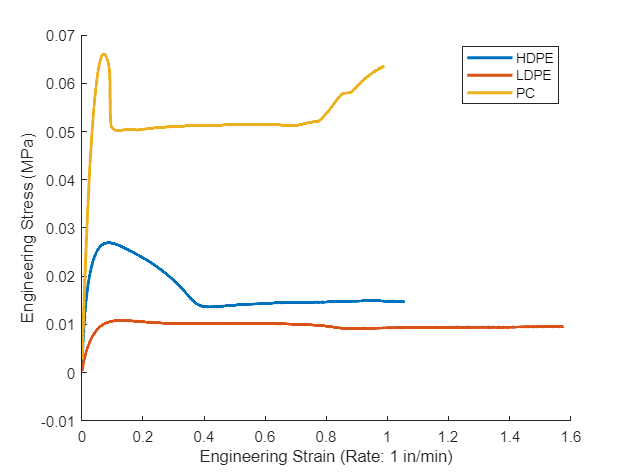


figure
hold on
plot(brass_eng_strain1, brass_eng_stress1, 'LineWidth', 2);
plot(al2024_eng_strain1, al2024_eng_stress1, 'LineWidth', 2);
plot(al6061_eng_strain1, al6061_eng_stress1, 'LineWidth', 2);
xlabel("Engineering Strain (Rate: 1 in/min)");
ylabel("Engineering Stress (MPa)");
legend("HDPE","LDPE","PC");
hold off

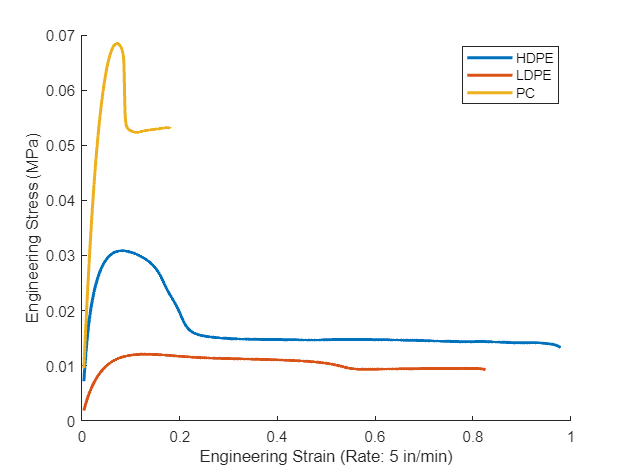


figure
hold on
plot(brass_eng_strain5, brass_eng_stress5, 'LineWidth', 2);
plot(al2024_eng_strain5, al2024_eng_stress5, 'LineWidth', 2);
plot(al6061_eng_strain5, al6061_eng_stress5, 'LineWidth', 2);
xlabel("Engineering Strain (Rate: 5 in/min)");
ylabel("Engineering Stress (MPa)");
legend("HDPE","LDPE","PC");
hold off

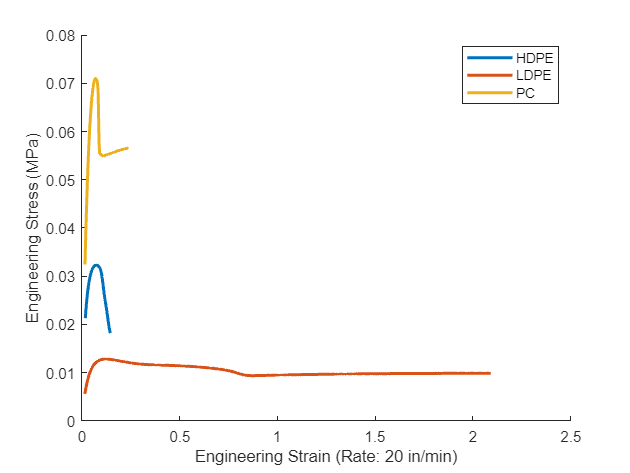


figure
hold on
plot(brass_eng_strain20, brass_eng_stress20, 'LineWidth', 2);
plot(al2024_eng_strain20, al2024_eng_stress20, 'LineWidth', 2);
plot(al6061_eng_strain20, al6061_eng_stress20, 'LineWidth', 2);
xlabel("Engineering Strain (Rate: 20 in/min)");
ylabel("Engineering Stress (MPa)");
legend("HDPE","LDPE","PC");
hold off

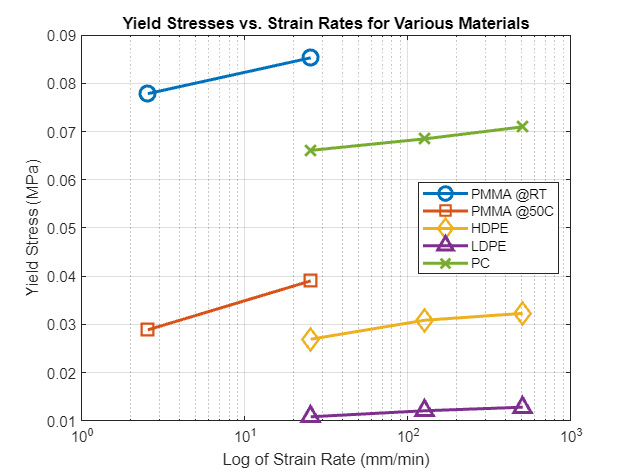


PMMA_rates = [2.54, 25.4];
rates = [25.4, 127, 508];

PMMA_rt_yield = [max(PMMA_rt1_egrstress),max(PMMA_rt2_egrstress)];
PMMA_50_yield = [max(PMMA_501_egrstress),max(PMMA_502_egrstress)];

HDPE_yield = [max(brass_eng_stress1), max(brass_eng_stress5), max(brass_eng_stress20)];
LDPE_yield = [max(al2024_eng_stress1), max(al2024_eng_stress5), max(al2024_eng_stress20)];
PC_yield = [max(al6061_eng_stress1), max(al6061_eng_stress5), max(al6061_eng_stress20)];

% Plot all on one plot
figure;
semilogx(PMMA_rates, PMMA_rt_yield, 'o-', 'LineWidth', 2, 'MarkerSize', 10);
hold on;
semilogx(PMMA_rates, PMMA_50_yield, 's-', 'LineWidth', 2, 'MarkerSize', 10);
semilogx(rates, HDPE_yield, 'd-', 'LineWidth', 2, 'MarkerSize', 10);
semilogx(rates, LDPE_yield, '^-', 'LineWidth', 2, 'MarkerSize', 10);
semilogx(rates, PC_yield, 'x-', 'LineWidth', 2, 'MarkerSize', 10);

title('Yield Stresses vs. Strain Rates for Various Materials');
xlabel('Log of Strain Rate (mm/min)');
ylabel('Yield Stress (MPa)');
legend('PMMA @RT', 'PMMA @50C', 'HDPE', 'LDPE', 'PC', 'Location', 'Best');
grid on;

set(gca, 'XScale', 'log'); % Explicitly set the x-axis to logarithmic scale

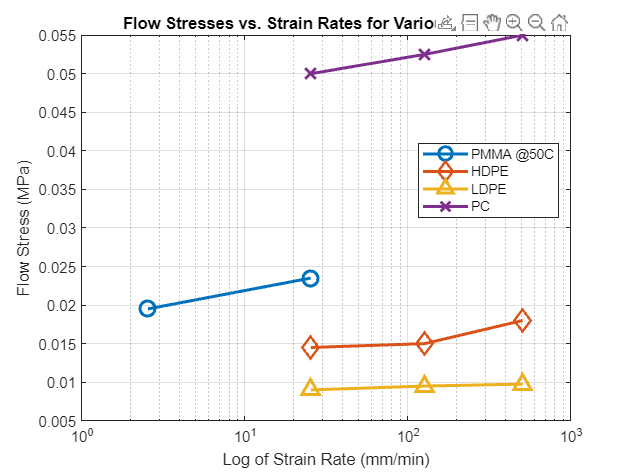


HDPE_flow = [0.0145, 0.015, 0.018];
LDPE_flow = [0.009, 0.0095, 0.00975];
PC_flow = [0.05, 0.0525, 0.055];
PMMA_flow = [0.0195, 0.0235];

% Plot all on one plot
figure;
semilogx(PMMA_rates, PMMA_flow, 'o-', 'LineWidth', 2, 'MarkerSize', 10);
hold on;
semilogx(rates, HDPE_flow, 'd-', 'LineWidth', 2, 'MarkerSize', 10);
semilogx(rates, LDPE_flow, '^-', 'LineWidth', 2, 'MarkerSize', 10);
semilogx(rates, PC_flow, 'x-', 'LineWidth', 2, 'MarkerSize', 10);

title('Flow Stresses vs. Strain Rates for Various Materials');
xlabel('Log of Strain Rate (mm/min)');
ylabel('Flow Stress (MPa)');
legend('PMMA @50C', 'HDPE', 'LDPE', 'PC', 'Location', 'Best');
grid on;